% evaluacion_ruta_cobertura.mlx

# Evaluacion de rutas utilizando un planificador de cobertura.

by AG ariel.guerrero@uc.edu.py 27-07-2024

### Referencia:

[1]"Optimally Survey and Customize Coverage of Region of Interest" disponible en [https://la.mathworks.com/help/uav/ug/optimally-survey-and-customize-coverage-of-region-of-interest-using-coverage-planner.html](https://la.mathworks.com/help/uav/ug/optimally-survey-and-customize-coverage-of-region-of-interest-using-coverage-planner.html)

[2] Torres, Marina, David A. Pelta, José L. Verdegay, and Juan C. Torres. “Coverage Path Planning with Unmanned Aerial Vehicles for 3D Terrain Reconstruction.” Expert Systems with Applications 55 (August 2016): 441–51. [https://doi.org/10.1016/j.eswa.2016.02.007.](https://doi.org/10.1016/j.eswa.2016.02.007.)

[3] Li, Yan, Hai Chen, Meng Joo Er, and Xinmin Wang.  “Coverage Path Planning for UAVs Based on Enhanced Exact Cellular Decomposition Method.” Mechatronics 21, no. 5 (August 2011): 876–85. [https://doi.org/10.1016/j.mechatronics.2010.10.009.](https://doi.org/10.1016/j.mechatronics.2010.10.009.)

### Antecedentes

 La planificación de cobertura (CPP - Coverture Path Planning) es el proceso de encontrar un plan de ruta óptimo para que un UAV inspeccione toda la región de una determinada área geográfica.

 Para inspeccionar una región, un UAV típicamente vuela en una dirección y utiliza giros en ángulo recto para alternar la dirección.  Una buena opción es descomponer el área en subáreas convexas y luego, puedes elegir de manera óptima una estrategia de cobertura que sea mejor para cada subregión y, posteriormente, conectar las rutas para completar la misión.

clear variables
close all
clc

###  Defina la region de interes

Para comenzar la planificación de cobertura, primero debes definir la región de interés como un polígono o un conjunto de polígonos. Primero, crea el eje geográfico, establece los  límites de latitud y longitud, y calcula la media de los límites para obtener el geocentro  del área visualizada. Establece la altura de referencia en 200 metros.

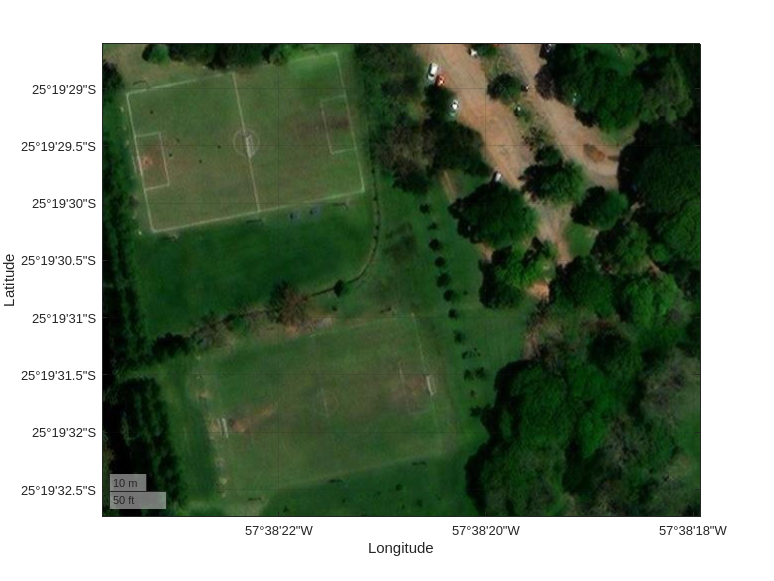

gax = geoaxes(Basemap="satellite");     % Informacion obtenida de google earth
latlimits = [-25.3257611 -25.3246139]; % ROI-01 y R0I-02
lonlimits = [-57.6396222 -57.6386111];
geolimits(latlimits,lonlimits);
geocenter = [mean(latlimits) mean(lonlimits) 0];
refHeight = 3;
hold on

Defina los vértices del polígono de manera interactiva seleccionando puntos en el mapa, o puedes usar vértices predefinidos almacenados en predefinedROI.mat para definir el polígono, la ubicación de despegue y la ubicación de aterrizaje. Por defecto, este script utiliza  puntos predefinidos. Para definir el polígono de manera interactiva, establece interactiveROI en true.

interactiveROI = false;
load predefinedROI.mat
GraficarDespegueROIAterrizaje(gax,takeoffLat,takeoffLon,landLat,landLon,llapoints);